# Approximation of Curves by Line Segments using Dynamic Programming 

- Bellman, Richard. "On the approximation of curves by line segments using dynamic programming." *Communications of the ACM* 4.6 (1961): 284.

- Stone, Henry. "Approximation of curves by line segments." *Mathematics of Computation* 15.73 (1961): 40-47.

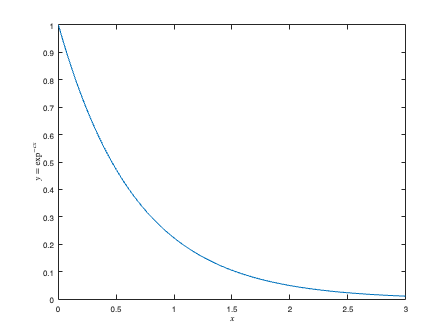

clc; clear; close all; 

dx = 0.01; 
x  = (0:dx:3)'; 
f  = @(x, c) exp(-c*x);

c = 1.5; 
y = f(x,c); 

a = 1;
b = length(x);

figure; plot(x,y); xlabel('$x$',Interpreter='latex'); ylabel('$y = \exp^{-cx}$',Interpreter='latex')

## Case 1:

feval = nan(size(x));
idx   = nan(size(x));
% exhaustive minimum search 
for i = (a+1):(b-1)
    feval(i)   = errorFunction(x,y,i,b) + errorFunction(x,y,a,i);
    [~,idx(i)] = min(feval);
end
% backtrace 
u1 = idx(end-1);
%  breakpoints 
u  = [x(1),x(u1),x(end)]

u =          0    0.9100    3.0000


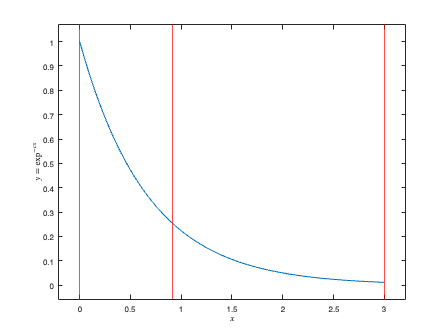

figure; plot(x,y); xlabel('$x$',Interpreter='latex'); ylabel('$y = \exp^{-cx}$',Interpreter='latex')
hold on; xline(u,Color='r'); axis('padded'); hold off; 

## Case 2: 

% storage for current stage
feval = nan(size(x));
idx   = nan(size(x));
% storage for next stage
idx12 = nan(size(x));
f12   = nan(size(x)); 
% exhaustive minimum search 1
for i = (a+1):(b-1) % u2 grid
    % exhaustive minimum search 2
    jgrid = ((a+1):(i-1))';
    if ~isempty(jgrid)
        fgrid = nan(size(jgrid));
        for j = 1:length(jgrid)
            fgrid(j) = errorFunction(x,y,a,jgrid(j)) + errorFunction(x,y,jgrid(j),i) ;
        end
        [f12(i),xx] = min(fgrid);
        idx12(i)    = jgrid(xx); 
        feval(i)    = errorFunction(x,y,i,b) +  f12(i);
        [~, idx(i)] = min(feval);
    end
end
% backtrace 
u2 = idx(end-1); 
u1 = idx12(u2);
%  breakpoints 
u  = sort([x(1),x(u1),x(u2),x(end)])

u =          0    0.5400    1.3600    3.0000


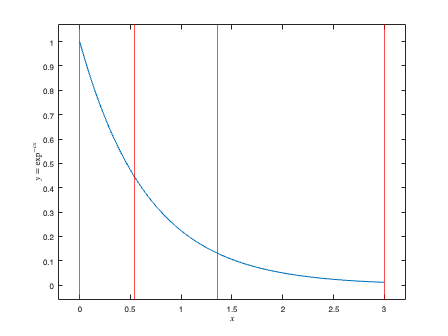

figure; plot(x,y); xlabel('$x$',Interpreter='latex'); ylabel('$y = \exp^{-cx}$',Interpreter='latex')
hold on; xline(u,Color='r'); axis('padded'); hold off; 

## Case 3:

% storage for current stage
feval = nan(size(x));
idx   = nan(size(x));
% storage for next stage
idx23 = nan(size(x));
f23   = nan(size(x));
% exhaustive minimum search 1
for i =  (a+1):(b-1)
    % exhaustive minimum search 1
    jgrid = ((a+1):(i-1))';
    if ~isempty(jgrid)
        fgrid = nan(size((a+1):(i-1)));
        for  j = 1:length(jgrid)
            fgrid(j) =  errorFunction(x,y,jgrid(j),i)  + f12(jgrid(j));
        end
        [f23(i),xx] = min(fgrid);
        idx23(i)    = jgrid(xx);
        feval(i) = errorFunction(x,y,i,b) +  f23(i);
    end
    [~, idx(i)] = min(feval);
end
% backtrace 
u3 = idx(end-1); 
u2 = idx23(u3);
u1 = idx12(u2);
%  breakpoints 
u  = sort([x(1),x(u1),x(u2),x(u3),x(end)])

u =          0    0.3900    0.9000    1.6400    3.0000


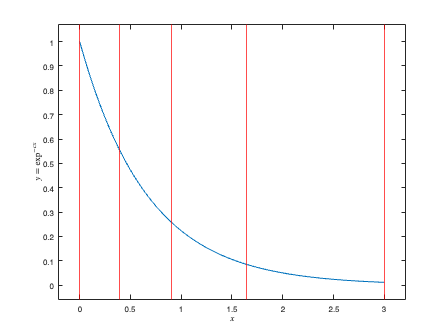

figure; plot(x,y); xlabel('$x$',Interpreter='latex'); ylabel('$y = \exp^{-cx}$',Interpreter='latex')
hold on; xline(u,Color='r'); axis('padded'); hold off; 